# Spike Raster Plot

A spike raster plot is a way of showing discrete event times (typically neuron firing times or "spike" times) as a function of time and optionally trial number and neuron group name.

## Simple Example

Start with very simple data.

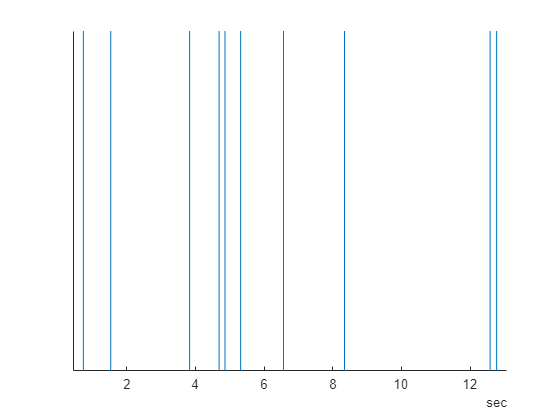

times = seconds((1:10) + randn(1,10));
spikeRasterPlot(times)

## More complicated example

Imagine you are running an experiment. You recorded from the brain while you have a light flashing once every minute.

After finishing the recording, you have a list of times when different neurons in the brain fired, and you want to determine whether there is any pattern to the firing.

clear
[spiketimes, trials, groups, trialStarts] = createExampleData;
whos

  Name                Size            Bytes  Class       Attributes

  groups           4178x1             33424  double                
  spiketimes       4178x1             33426  duration              
  trialStarts         1x20              162  duration              
  trials           4178x1             33424  double                



To start with, you just plot the firing times.

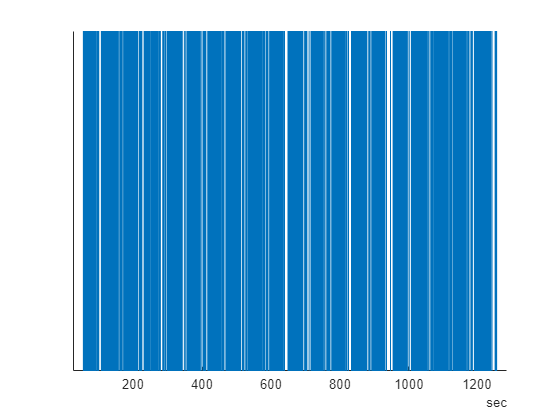

spikeRasterPlot(spiketimes)

That is a lot to process, but you were also provided with a second input indicating which spike time came from which trial.

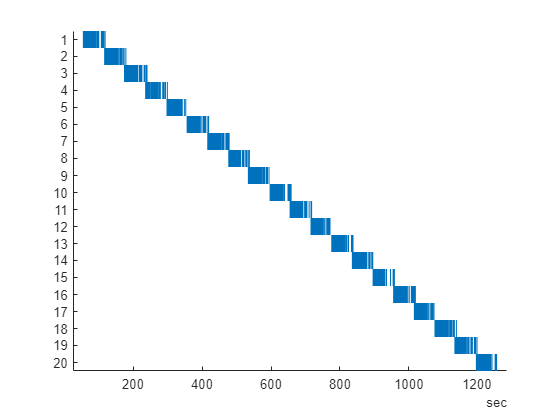

s = spikeRasterPlot(spiketimes, trials);

That is a better, but still a lot too dense to really interpret what is happening. The data came from multiple trials that were run back-to-back, so let's shift the spikes based on the start time of each trial.

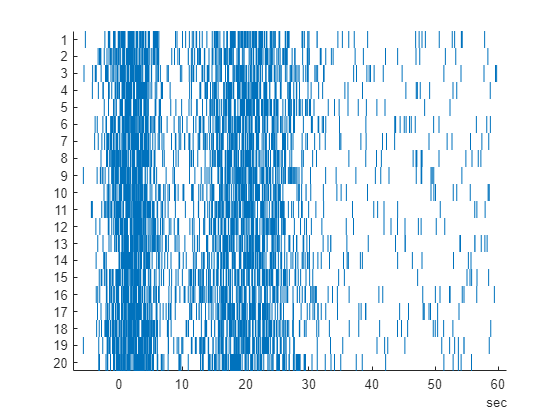

s.AlignmentTimes = trialStarts;

It is starting to look like there is some structure in the data. There are more events around 2 seconds and 20 seconds than elsewhere in the data.

There is one more piece of information provided. It turns out this data came from two different neurons. Let's color code the spikes based on the identity of the neuron.

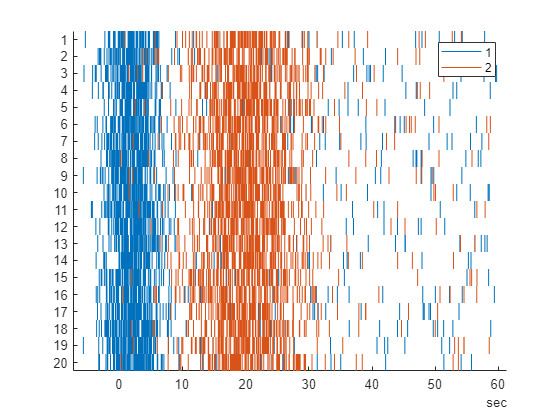

s.GroupData = groups;

Now you can see that the two neurons are firing at different times relative to the start of the trial.